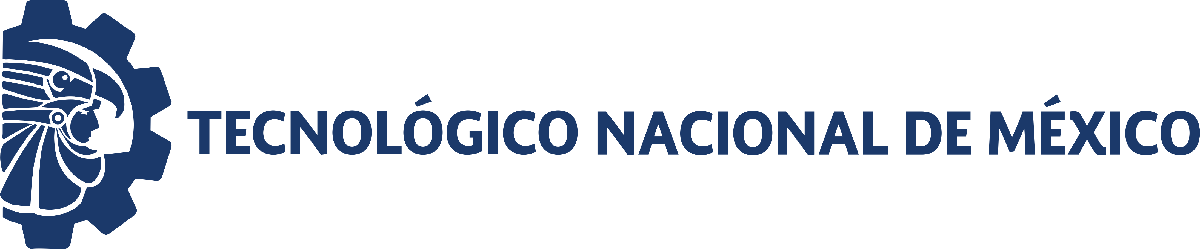                                 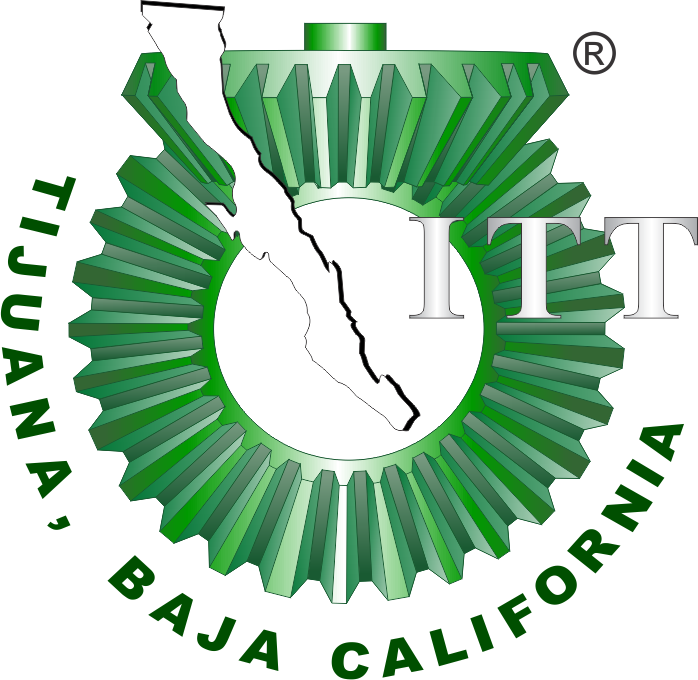

# Práctica cuatro: Modelado y control de sistema endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

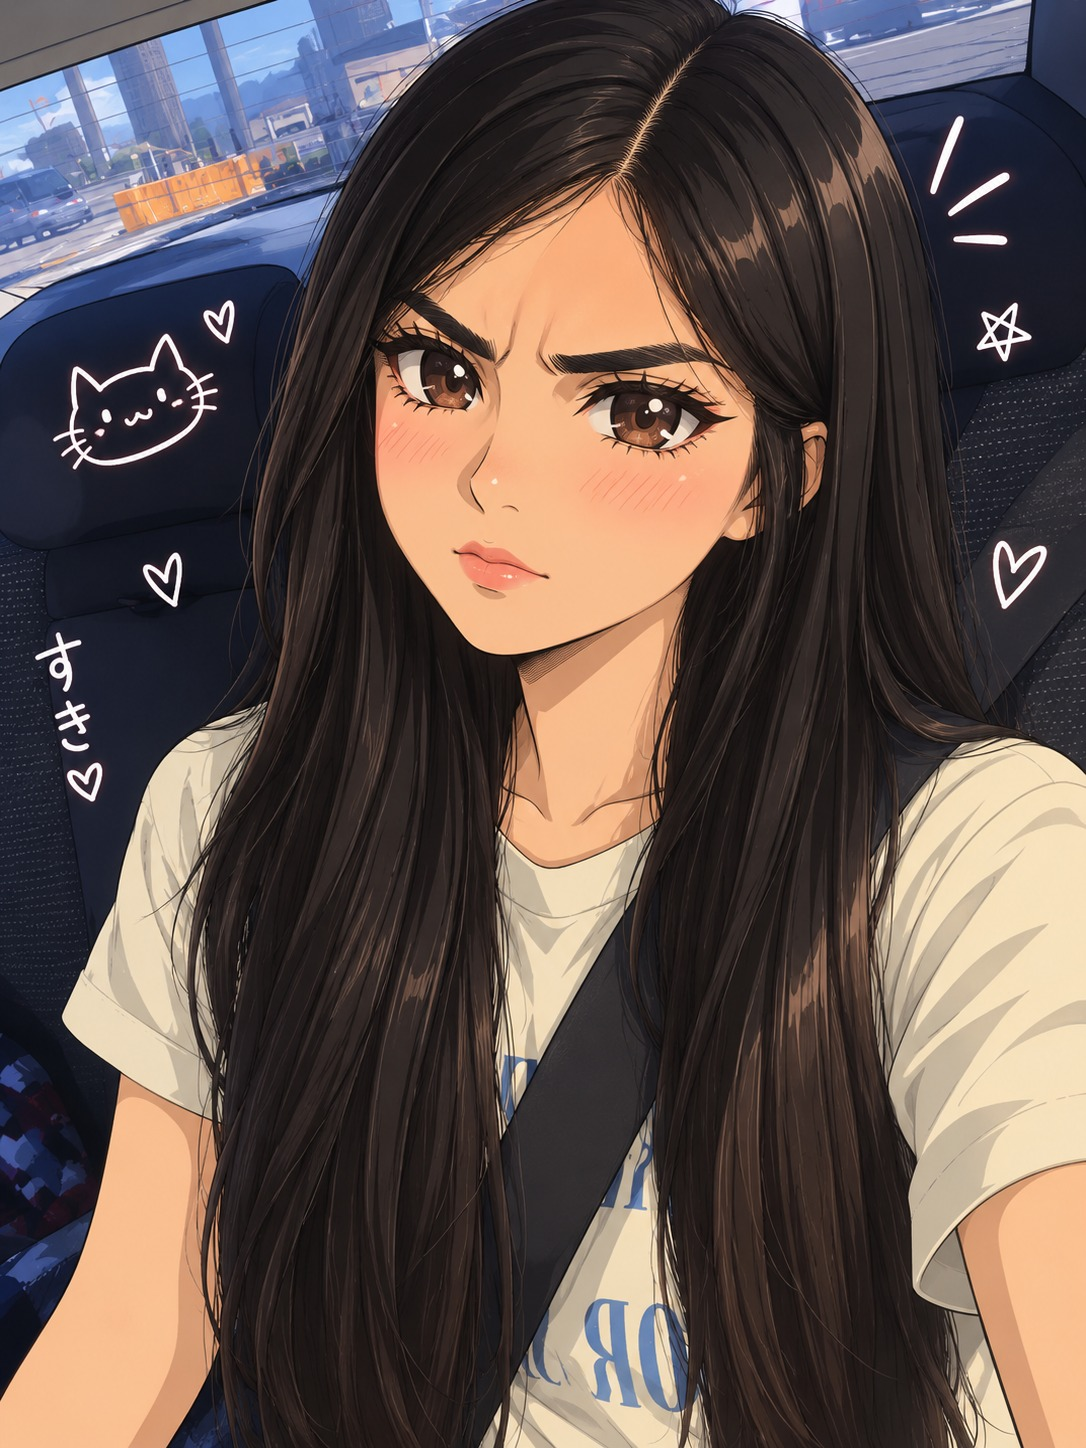

Nombre del alumno: Briseida Prado Acosta

Número de control: 23210715

Correo institucional: 23210715**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Prado23210715YP4')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('Prado23210715YP4', parameters);

## **Respuesta del sistema**

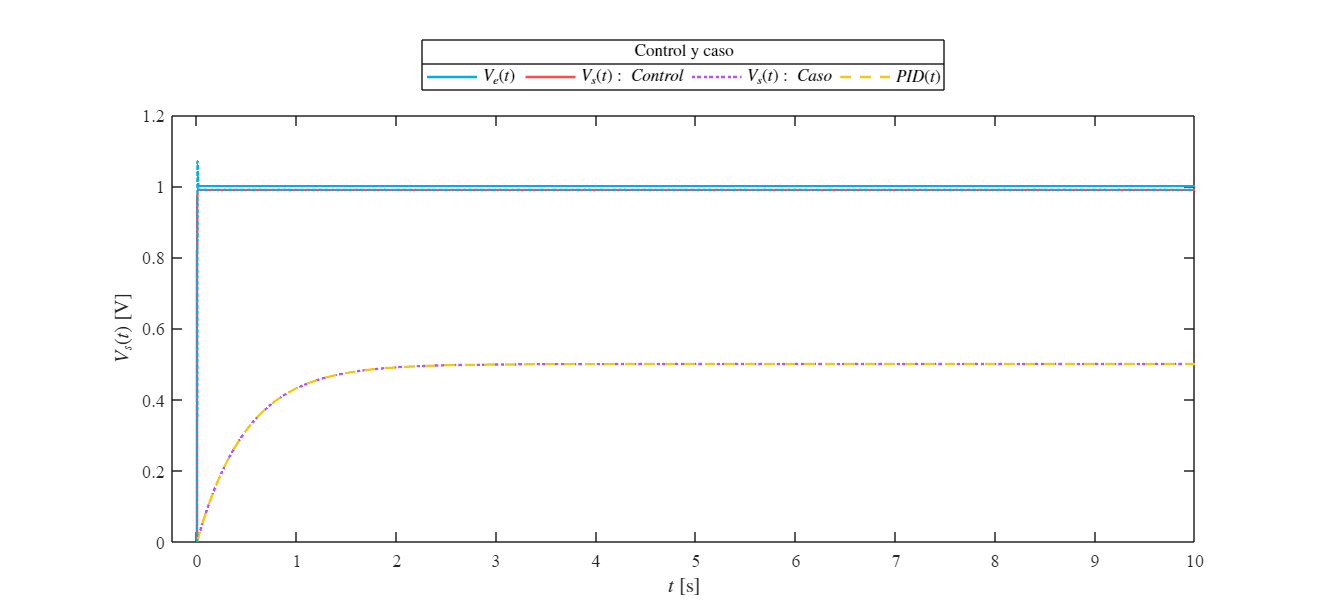

plotsignals(x.t,x.F,x.Pp1,x.Pp2,x.PI,x.Pp3)

## Función: Respuestas a las señales 

function plotsignals(t,F,Pp1,Pp2,PI,Pp3)

set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,11,5])
set(gca,'fontname','times new roman','fontsize',11)

hold on;
grid off;
box on;

clr1 = [0, 174, 239]/255;
clr2 = [255, 75, 75]/255;
clr3 = [179, 85, 255]/255;
clr4 = [0.95, 0.78, 0.10];

order = [clr1;clr2;clr3;clr4]; colororder(order)

plot(t,F,'-',t,Pp1,'-',t,Pp2,':',t,PI,'--',t,Pp3,':','LineWidth',1.5);

L = legend('$V_e(t)$', '$V_s(t):\ Control$','$V_s(t):\ Caso$', '$PID(t)$');

set(L,'interpreter','latex', 'location','northoutside', 'orientation','horizontal')

title(L,'Control y caso')

xlabel('$t$ [s]','interpreter','latex')
ylabel('$V_s(t)$ [V]','interpreter','latex')

xlim([-0.25 10]);
xticks(0:1:10)

ylim([0 1.2]);
yticks(0:0.2:1.2)

exportgraphics(gcf,'Control_caso_matlab.pdf','contenttype','vector')

end